**Lab 5**

My partner and I will be working on Higgs data. I will be doing the data set named 1000/1200.

First, I need to import the data.

h5disp("higgs_100000_pt_1000_1200.h5")

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgsData = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcdData = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

Sort the data into individual vectors. "h" prefixes are for higgs data, "q" prefixes are for background data.

hPT = higgsData(1,:);
qPT = qcdData(1,:);

PT is the transverse (xy) momentum, given by pt = sqrt(px^2 + py^2), where px and py are the momenta along x and y.

hETA = higgsData(2,:);
qETA = qcdData(2,:);

ETA is the pseudorapidity, given by -ln(tan(ø/2))-0.5ln((abs(p)+pl)/(abs(p)-pl))

hPHI = higgsData(3,:);
qPHI = qcdData(3,:);

PHI is the azimuthal angle, given by arccos(x/r)

hMASS = higgsData(4,:);
qMASS = qcdData(4,:);

MASS is the mass invariant, given by E^2 = p^2 + m^2 (natural units).

hEE2 = higgsData(5,:);
qEE2 = qcdData(5,:);

EE2 is the 2-point ECF ratio, given by sum over i<j in J of (p_t,i * p_t,j * deltaR_ij * 1/(p_t,J)^2). This observable shows 2-prong particle decay.

hEE3 = higgsData(6,:);
qEE3 = qcdData(6,:);

EE3 is the 3-point ECF ratio, given by sum over i<j<k in J of (p_t,i * p_t,j * p_t,k * deltaR_ij * deltaR_ik * deltaR_jk * 1/(p_t,J)^3). This observable shows 3-prong particle decay.

hD2 = higgsData(7,:);
qD2 = qcdData(7,:);

D2 is the 3-to-2 point ECF ratio, given by EE3/(EE2)^3

hANG = higgsData(8,:);
qANG = qcdData(8,:);

ANG is the angularity, given by 1/m_J * sum over i in J of (E_i * cos^3(ø_i) / (sin^2(ø_i)))

hT1 = higgsData(9,:);
qT1 = qcdData(9,:);

I'm honestly unsure about what all of the T# variables are. I think they are somehow related to thrust, but I am unsure about what they may mean. I was not successful in finding answers in the few papers that I've looked at for the information.

hT2 = higgsData(10,:);
qT2 = qcdData(10,:);

hT3 = higgsData(11,:);
qT3 = qcdData(11,:);

hT21 = higgsData(12,:);
qT21 = qcdData(12,:);

hT32 = higgsData(13,:);
qT32 = qcdData(13,:);

hKTDELTAR = higgsData(14,:);
qKTDELTAR = qcdData(14,:);

KTDELTAR is deltaR of two subjects within the large-R jet. k_t is a jet-finding algorithm for hadron-hadron collisions.

Let's make some plots of the data to see what is going on.

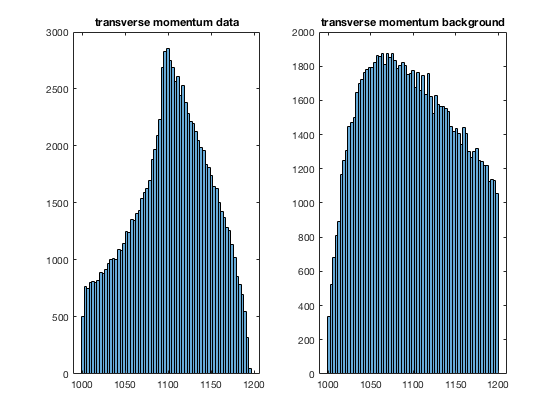

figure;
subplot(1,2,1);
histogram(hPT);
title('transverse momentum data');
subplot(1,2,2);
histogram(qPT);
title('transverse momentum background');

It looks like there is a significant difference between the data and the background — the data seems to start at lower values near x = 1000, increasing until ~1100 where it largely surpasses the expected background value, and then it drops off steeply to zero at 1200, whereas the background does not.

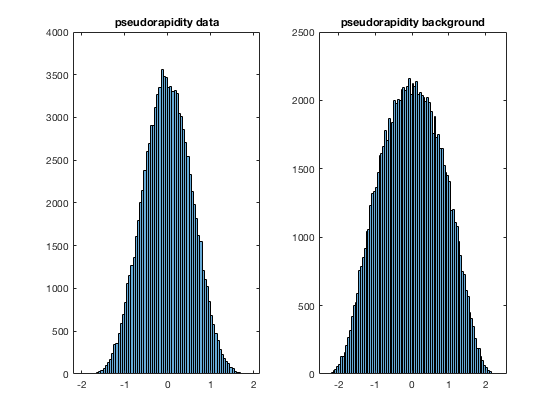

figure;
subplot(1,2,1);
histogram(hETA);
title('pseudorapidity data');
subplot(1,2,2);
histogram(qETA);
title('pseudorapidity background');

Both of these plots show that the pseudorapidity (data and background) appear Gaussian. We could do basic fits to these to see the parameters.

[muh,sigmah] = normfit(hETA)

muh = -1.7033e-05

sigmah = 0.5496

[muq,sigmaq] = normfit(qETA)

muq = 5.9326e-05

sigmaq = 0.8247

Both of the distributions have a mean very close to zero, and have comparable sigmas (~0.5 and ~0.8).

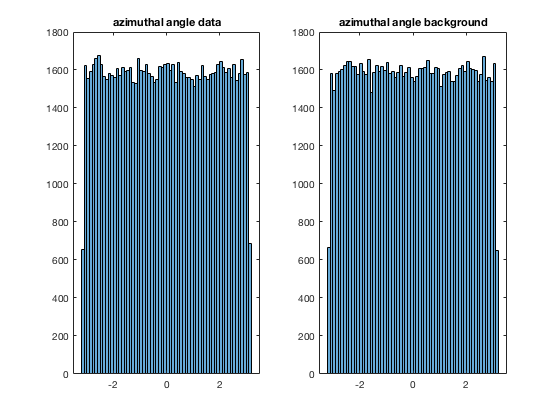

figure;
subplot(1,2,1);
histogram(hPHI);
title('azimuthal angle data');
subplot(1,2,2);
histogram(qPHI);
title('azimuthal angle background');

The azimuthal angle histograms are noisy, don't seem to have an easily-identifiable distribution, and are also hard to distinguish (the data has about the same distribution as the background).

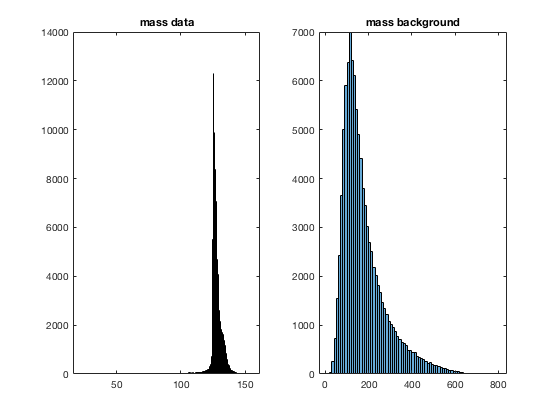

figure;
subplot(1,2,1);
histogram(hMASS);
title('mass data');
subplot(1,2,2);
histogram(qMASS);
title('mass background');

The mass distributions seem Rayleigh-like, which makes sense because the formula is E^2 = p^2 + m^2, which fits the Rayleigh model if both are distributed normally about zero. The data is more sharply peaked when compared to the background (higher values and steeper fall-off), and seems to be centered about a different value (~125 for data instead of ~180 for background).

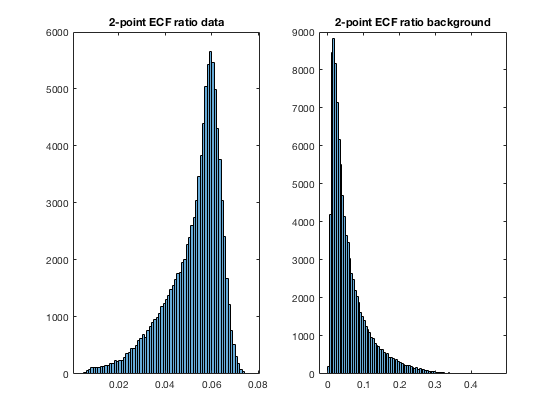

figure;
subplot(1,2,1);
histogram(hEE2);
title('2-point ECF ratio data');
subplot(1,2,2);
histogram(qEE2);
title('2-point ECF ratio background');

These histograms are a bit perplexing to me. The background looks Rayleigh, which doesn't really make much sense to me from its definition, while the data looks like some other distribution (unsure). They are also centered about different values, and have vastly different behaviors on the left sides of each respective mean.

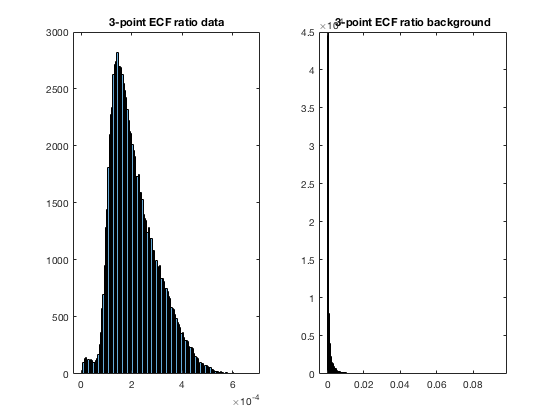

figure;
subplot(1,2,1);
histogram(hEE3);
title('3-point ECF ratio data');
subplot(1,2,2);
histogram(qEE3);
title('3-point ECF ratio background');

This behavior is somewhat similar to the EE2 case. The background is very sharply peaked at value ~4.5e4 around x = 0, whereas the data is centered at x=2e-4, and only reaches ~2800. The distributions look quite similar in shape, however.

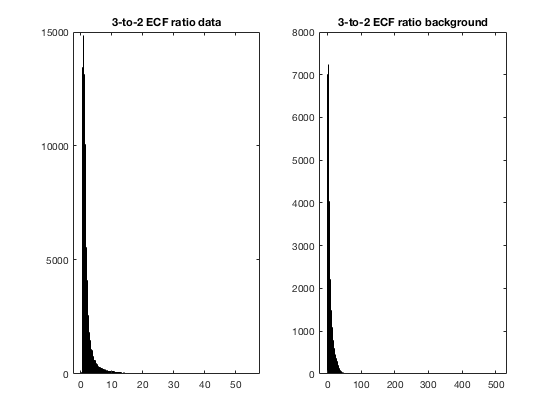

figure;
subplot(1,2,1);
histogram(hD2);
title('3-to-2 ECF ratio data');
subplot(1,2,2);
histogram(qD2);
title('3-to-2 ECF ratio background');

The data is much more sharply-peaked than the background. It falls off much quicker (~12, whereas background ~40), and has higher peaks. Both look somewhat Rayleigh-like, but unsure.

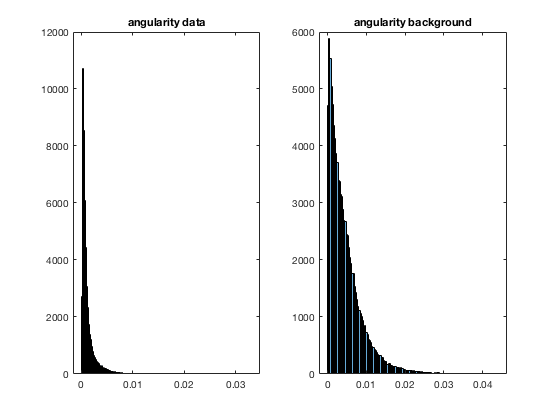

figure;
subplot(1,2,1);
histogram(hANG);
title('angularity data');
subplot(1,2,2);
histogram(qANG);
title('angularity background');

Similarly to the last plot, the angularity data is more sharp than the background. Higher peak, centered earlier, falls off quicker. Looks like a Rayleigh distribution as well.

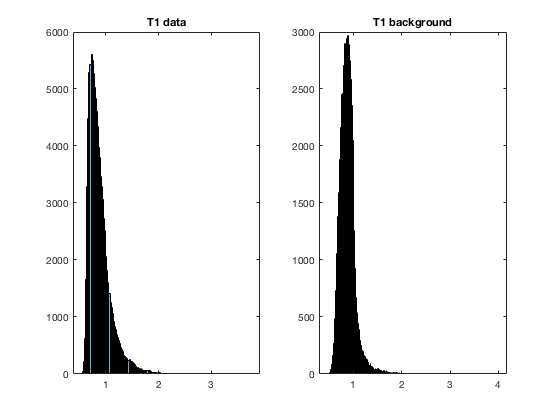

figure;
subplot(1,2,1);
histogram(hT1);
title('T1 data');
subplot(1,2,2);
histogram(qT1);
title('T1 background');

This time the background is a bit more "sharp," however the data does have a higher peak. Both are distributed with a mean about 1, unsure about the distribution (maybe Rayleigh), and the fall-off of the data is a bit shorter than that of the background.

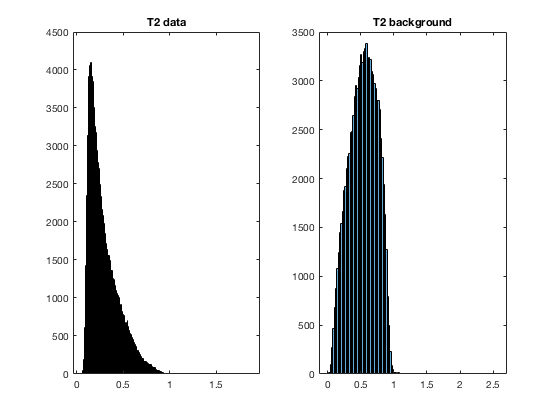

figure;
subplot(1,2,1);
histogram(hT2);
title('T2 data');
subplot(1,2,2);
histogram(qT2);
title('T2 background');

These look like different distributions, almost. The background is close to Gaussian, although it is slanted and does not have the right proportions/tail. The data is distributed about a different mean than the background, but they have somewhat comparable peaks, even though the distributions look different.

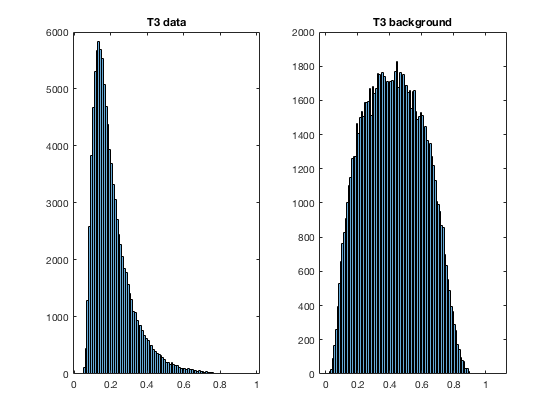

figure;
subplot(1,2,1);
histogram(hT3);
title('T3 data');
subplot(1,2,2);
histogram(qT3);
title('T3 background');

The background looks almost Gaussian, centered at about 0.4. The data does not represent that, being centered closer to 0.2, having a much sharper and higher peak, and a negligent tail on the left, while a much larger tail on the right. The data distribution looks Rayleigh-like.

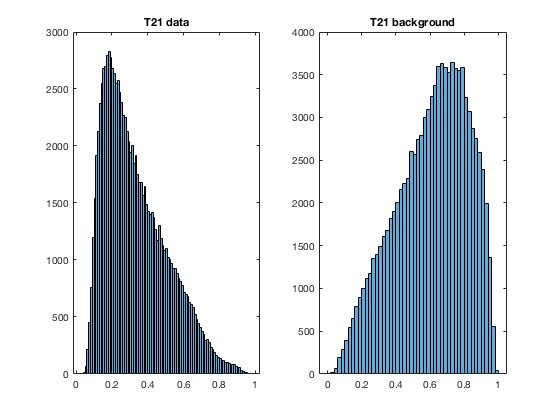

figure;
subplot(1,2,1);
histogram(hT21);
title('T21 data');
subplot(1,2,2);
histogram(qT21);
title('T21 background');

These two distributions look almost mirrored. There is a slow, stair-like climb on one side (left for background, right for data), and a more steep fall off on the opposite side. The data has a lower peak than that of the background (which is interesting, and a bit confusing), and they are centered at different values (data ~0.2, background ~0.8). Unsure about the mirroring of the plots here.

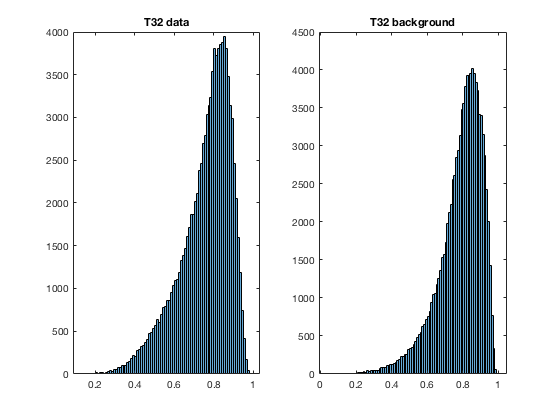

figure;
subplot(1,2,1);
histogram(hT32);
title('T32 data');
subplot(1,2,2);
histogram(qT32);
title('T32 background');

The background and the data look very similar. They reach similar peaks, have very similar-looking distributions, are centered about the same value, and have similar tails. The data seems like a replica of the background.

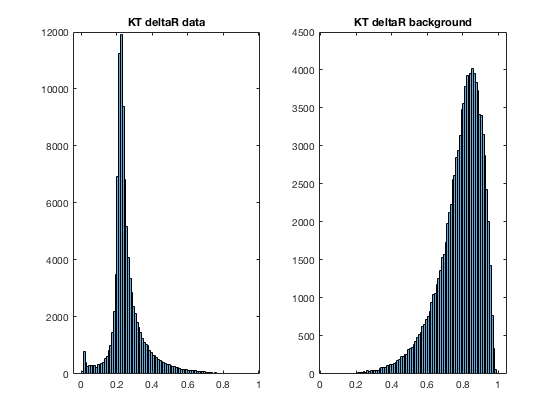

figure;
subplot(1,2,1);
histogram(hKTDELTAR);
title('KT deltaR data');
subplot(1,2,2);
histogram(qT32);
title('KT deltaR background');

These two distributions are quite interesting. The background differs quite a bit from the data distribution, in shape, center-value (0.8 for background, ~0.25 for data), and peak heights. It is weird to me that there aren't more data points measured that overlap with the background distribution, but I'm not sure what this means.